# Práctica 2

## 2.2. Calibración de una cámara

**Nombre:** Franck Michael Fierro Chicaiza

**Fecha:** 01/10/2023

Scritp generado por matlab con el código necesario para calibrar la cámara del dispositivo con imagenes de un tablero almacenadas en un directorio.

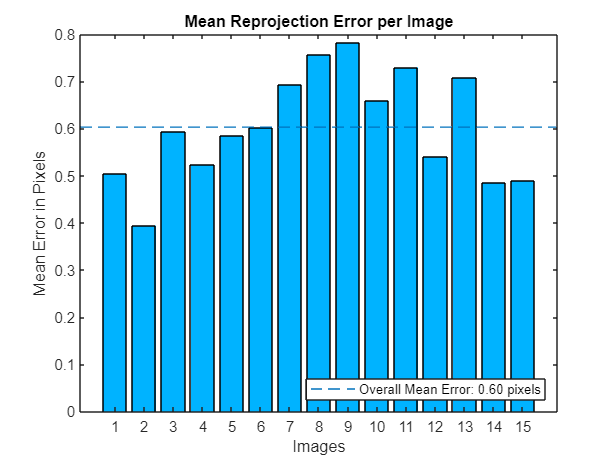

close all;
clear all;

% Auto-generated by cameraCalibrator app on 01-Oct-2023
%-------------------------------------------------------

% Define images to process
% Se cargan las imagenes mediante ruta absoluta
imageFileNames = {'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image1.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image2.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image3.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image4.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image9.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image10.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image11.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image12.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image13.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image14.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image15.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image16.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image17.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image20.png',...
    'C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image21.png',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames);
imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 21;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', true, 'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 3, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

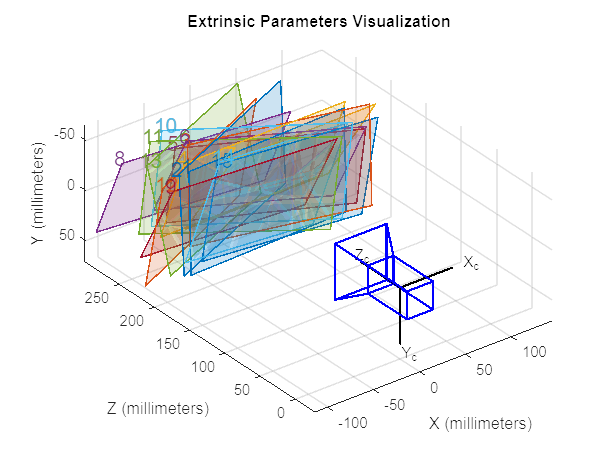


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  949.0697 +/- 1.4482      945.0094 +/- 1.3662  ]
Principal point (pixels):[  635.5565 +/- 1.3794      357.7340 +/- 1.1165  ]
Skew:                    [    2.6766 +/- 0.2218  ]
Radial distortion:       [   -0.0337 +/- 0.0058        0.1472 +/- 0.0299       -0.3289 +/- 0.0454  ]
Tangential distortion:   [   -0.0006 +/- 0.0003       -0.0044 +/- 0.0004  ]

Extrinsics
----------
Rotation vectors:
                         [    0.0102 +/- 0.0016        0.0067 +/- 0.0015       -0.0300 +/- 0.0002  ]
                         [    0.0002 +/- 0.0016       -0.3663 +/- 0.0016       -0.0642 +/- 0.0004  ]
                         [    0.0433 +/- 0.0016        0.2932 +/- 0.0016       -0.0469 +/- 0.0003  ]
                         [    0.4248 +/- 0.0015        0.0497 +/- 0.0016       -0.0599 +/- 0.0004  ]
                         [    0.3884 +/- 0.0015    


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
%showdemo('MeasuringPlanarObjectsExample')
%showdemo('StructureFromMotionExample')


## 2.2. Código extra

Una vez generado el script y comprendido el proceso de calibración se realizan una serie de ejercicios:

1. Cargue una de las imágenes utilizadas para la calibración y obtenga la imagen no distorsionada con la función `undistortImage. `Visualice la imagen antes y después de eliminar la distorsión.

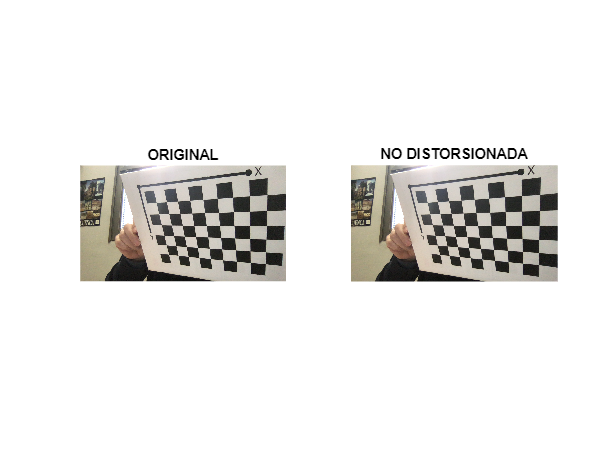

% Cargamos una de las imagenes seleccionadas en la calibracion
% Imagen 9 del directorio
I = imread('C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image9.png'); 

% Obtenemos la imagen no distorsionada
IUndis = undistortImage(I, cameraParams);

% Mostramos la imagen original y la que no tiene distorsion
h3 = figure();
subplot(1,2,1), imshow(I); title('ORIGINAL');
subplot(1,2,2), imshow(IUndis); title('NO DISTORSIONADA');

2. Obtenga la matriz de parámetros intrínsecos e identifique los distintos parámetros. 

% Sacamos los intrisecos de la camara mediante la calibracion realizada
% anteriormente
intrinsics = cameraParams.Intrinsics

intrinsics =   cameraIntrinsics with properties:

             FocalLength: [949.0697 945.0094]
          PrincipalPoint: [635.5565 357.7340]
               ImageSize: [720 1280]
        RadialDistortion: [-0.0337 0.1472 -0.3289]
    TangentialDistortion: [-5.9946e-04 -0.0044]
                    Skew: 2.6766
                       K: [3×3 double]


**Comentario:**

**Podemos observar los distintos parámtros:**

- **Distancia focal - Distancia entre la lente y el plano de la imagen**

- **Tamaño de la imagen**

- **Punto principal - Centro óptico de la cámara**

- **Distorsiones - Radiales y tangenciales**

**Son pámetros internos de la cámara**

3. Visualice una de las imágenes y los parámetros intrínsecos y extrínsecos que se corresponden con ella. ¿Si cargase otra imagen diferente cambiaría alguno de los parámetros intrínsecos o extrínsecos? Justifique la respuesta. Visualizar con otra imagen y verificar si es coherente.

% Imagen 9 
% Obtenemos los puntos de la imagen no distorsionada de la imagen 9 del ejercicio 1
[imagePoints, ~] = detectCheckerboardPoints(IUndis);

% Obtenemos los extrinsecos de la camara
% Usamos:
%   puntos de la imagen
%   puntos del mundo real (obtenidos de la calibracion)
%   intrisecos de la camara
extrinsics = estimateExtrinsics(imagePoints, worldPoints, intrinsics)

extrinsics =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-44.2165 -34.0247 261.9013]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics.R

ans =     0.8975    0.1721    0.4061
   -0.0019    0.9222   -0.3866
   -0.4410    0.3462    0.8280


% Imagen 17
% Aplicamos lo mismo con la imagen 17
I2 = imread('C:\Users\mfran\Desktop\Programas\Matlab\Practica2\checkerboard_pattern\Image17.png'); 
I2Undis = undistortImage(I2, cameraParams);
[imagePoints2, ~] = detectCheckerboardPoints(I2Undis);
extrinsics2 = estimateExtrinsics(imagePoints2, worldPoints, intrinsics)

extrinsics2 =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-103.7888 -55.4865 223.7721]
                 R: [3×3 double]
                 A: [4×4 double]


extrinsics2.R

ans =     0.9068    0.0772   -0.4144
    0.0239    0.9721    0.2335
    0.4209   -0.2217    0.8796


**Comentario:**

**Dado que las imágenes se han capturado con la misma cámara, los parámetros intrínsecos son constantes, ya que corresponden a la configuración interna de la cámara y se detallan en la sección anterior. Estos parámetros se obtienen para ambas imágenes de la misma forma, ya que provienen de la misma cámara.**

**Por otro lado, podemos observar que los valores extrínsecos sí cambian. Esto se deduce de los valores de 'Traslation' y 'Rotation' que representan la posición y rotación de la cámara. En resumen cada imagen puede tener sus propios valores de matriza de rotación y vector de traslación, variando para cada imagen capturada por una cámara específica.**

4. Proyecte los puntos de un cubo 3D en la imagen no distorsionada usando la función `world2img`.

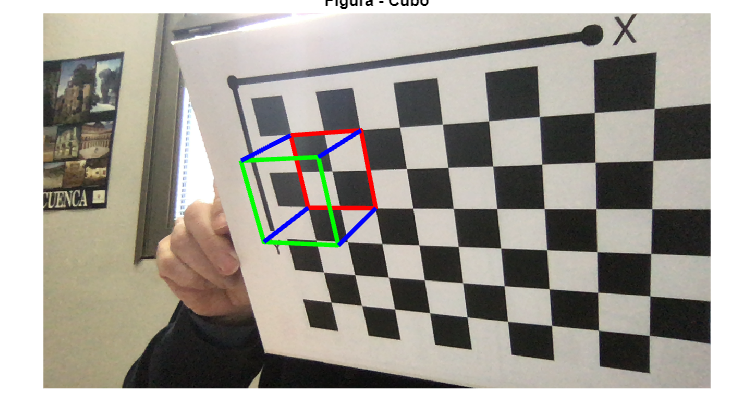

% Utilizamos la imagen 9 del ejercicio 1
% Obtenemos el equivalente de los puntos reales en la imagen
zCoord = zeros(size(worldPoints, 1), 1);
worldPoints = [worldPoints, zCoord];
imagePoints = world2img(worldPoints, extrinsics, intrinsics);

% Mostramos la imagen y dibujamos un cubo sobre ella
h4 = figure();
imshow(IUndis); title("Figura - Cubo");
hold on;

% Indice de los puntos para realizar el trazado
coords = [1 3 15 13 1];

% Se realiza el trazado de lineas sobre la superficie del tablero
xCoords = [imagePoints(coords, 1)];
yCoords = [imagePoints(coords, 2)];
plot(xCoords, yCoords, "r",'LineWidth', 3);

% Se realiza el trazado de lineas con profundidad añadida
newPoints = [worldPoints(coords, 1:2) [-42; -42; -42; -42; -42]];
newPoints = world2img(newPoints, extrinsics, intrinsics);
plot(newPoints(:, 1), newPoints(:, 2), "g",'LineWidth', 3);

% Se unen con lineas el dibujo del tablero con el que tiene profundidad
for i = 1:length(coords) - 1
    plot([xCoords(i), newPoints(i, 1)], [yCoords(i), newPoints(i, 2)], "b",'LineWidth', 3);
end

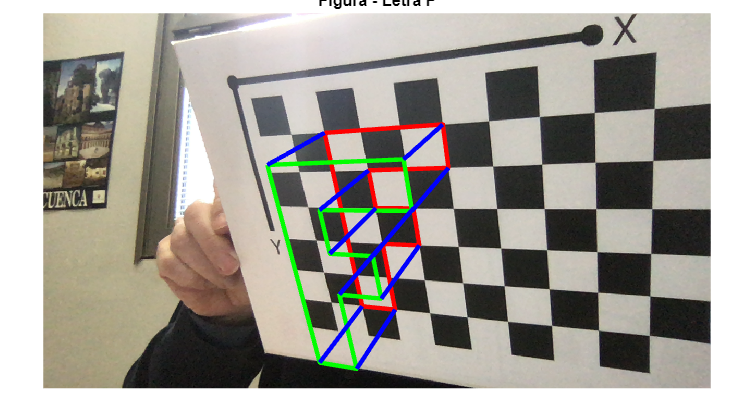

% Mostramos la imagen y dibujamos una letra sobre ella
h5 = figure();
imshow(IUndis); title("Figura - Letra F");
hold on;

% Indice de los puntos para realizar el trazado
coords = [1 6 12 10 16 15 9 8 20 19 1] + 6; % Anadimos desplazamiento

% Se realiza el trazado de lineas sobre la superficie del tablero
xCoords = [imagePoints(coords, 1)];
yCoords = [imagePoints(coords, 2)];
plot(xCoords, yCoords, "r",'LineWidth', 3);

% Se realiza el trazado de lineas con profundidad añadida
newPoints = [worldPoints(coords, 1:2) repmat(-50, length(coords), 1);];
newPoints = world2img(newPoints, extrinsics, intrinsics);
plot(newPoints(:, 1), newPoints(:, 2), "g",'LineWidth', 3);

% Se unen con lineas el dibujo del tablero con el que tiene profundidad
for i = 1:length(coords) - 1
    plot([xCoords(i), newPoints(i, 1)], [yCoords(i), newPoints(i, 2)], "b",'LineWidth', 3);
end